**Preliminary Work - Exp 7 Part-1**

**Defne ODABAŞI-2443604**

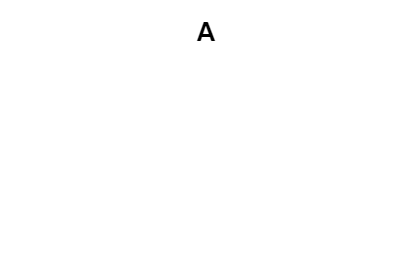

A = ones(81,81);
figure
imshow(A)
title('A'); % Place title here

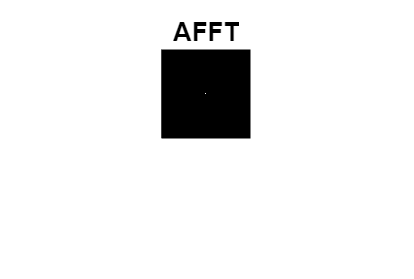

AFFT = fft2(A);
AFFT = AFFT/max(max(abs(AFFT)));
figure
imshow(fftshift(abs(AFFT))) %shift the zero freq components to the center of the array
title('AFFT'); 

'A' matrix only consist of 1's which indicates a constant image, the has only a peak at zero frequency.

This is because in the constant image there are no variations throughout the image. This also means that there are no high frequency components. 

The magnitude of the 2FFT before normalization is 6561 which is 81*81. By normalization we set its magnitude to 1. 

In matlab display range for fgrayscale image is between [0,1] and for values greater than 1 (high), it displays with 1. Therefore by normalization we are able to epress the image within the range without lossing information.

fftshift is used to shift the zero frequeny component to the center of the array before the plotting.

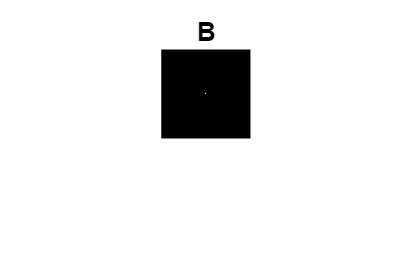

B = zeros(81,81);
B(41,41) = 1;
figure
imshow(B)
title('B'); % Place title here

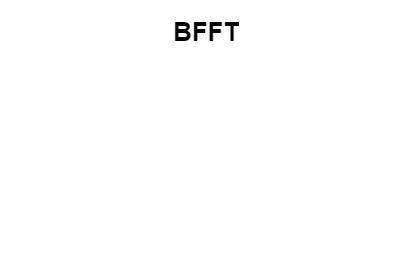

BFFT = fft2(B);
BFFT = BFFT/max(max(abs(BFFT)));
figure
imshow(fftshift(abs(BFFT)))
title('BFFT'); 

Since B consists of zeros everywhere except for a single pixel at the center which is set to 1, we can see that it has a delta function characteristic. The 2D FFT of the delta function is a constant value across all frequencies since it essentially consists of all frequecny components with same magniude. The magnitude of the 2FFT of B is 1 everywhere. This can be also observed from the formula where the H(k1,k2) = 1* e^ (-j2pi41(k1 + k2) /81) which has a magnitude of 1 everywhere.

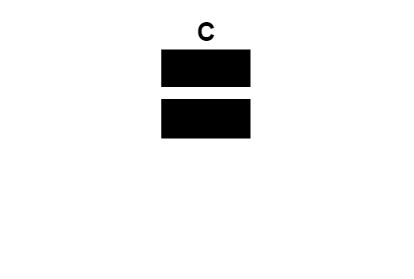

C = zeros(81,81);
C(35:45,:) = 1;
figure
imshow(C)
title('C');

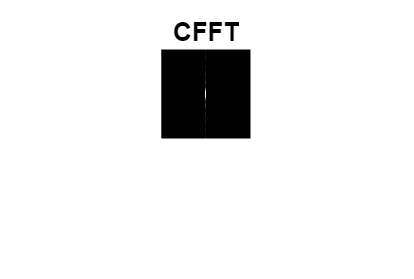

CFFT = fft2(C);
CFFT = CFFT/max(max(abs(CFFT)));
figure
imshow(fftshift(abs(CFFT)))
title('CFFT');

As seen from the Figure, C only consists of a horizontal strip of ones in the center and zeros elsewhere. The horizontal trip can be interpreted as change along the vertical axis and constant value along the horizantal direction. 

We would expect that transition from zeros to ones and back to zeros create high frequency components.

If we fix n1, we have constant values along n2, therefore the ftt has 0 components everywhere except when n2 is fixed and we have a strip along the horizantal which results in a change in the frequency. Only k2=0 has nonzero values as expected which equals to the summation of e^(-j2pink1/81) for 35<=n1<=45 and 1<=k1<=81.

There are total of 11*81 ones.  Therefore the maximum magnitude of the frequency component is 891 at k1=0,k2=0 frequency. The normalization is done based on this magnitude.

After the fftshift we can observe that the CFFT has a horizontal line at the center which showing the frequency change along the vertical.

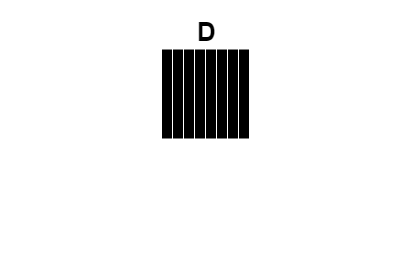

D = zeros(81,81);
for dd=0:8
    D(:,10*dd+1) = 1; %1,11,21,31,41,51,61,71,81
end
figure
imshow(D)
title('D');

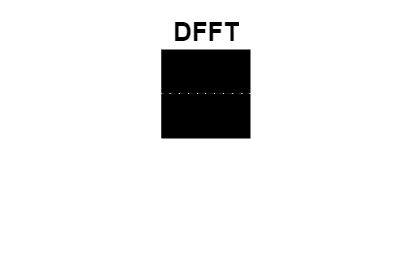

DFFT = fft2(D);
DFFT = DFFT/max(max(abs(DFFT)));
figure
imshow(fftshift(abs(DFFT)))
title('DFFT');

This time D has vertical stripts which means the frequecny should be constant along the vertical and changing along the horizantal axis.

The maximum magnitude is 81*9 as expected since we have 9 strips. 

From the magnitude DFFT plot, we can observe the effect. The frequency changes occur along the horizantal.

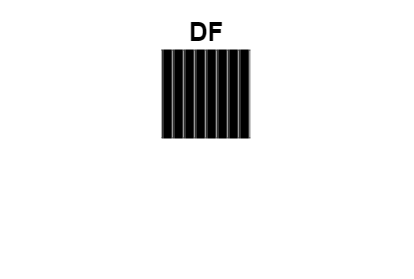

F1 =  [0 1/5 0; 1/5 1/5 1/5; 0 1/5 0];
DF = filter2(F1,D);
figure
imshow(DF)
title('DF');

This is a lowpass filter since the F1 filter has equal weights around the center. From this filter we can observe the averaging effect around the neightbours. This smooths out rapic changes. We can see that transition the strips of D softens after the filter is applied.

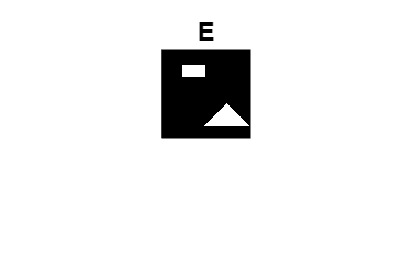

E = zeros(81,81);
E(15:25, 20:40) = 1;
for ee=50:70
    E(ee,60+50-ee:60-50+ee) = 1;
end
figure
imshow(E)
title('E');

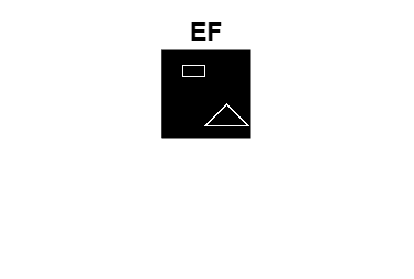


F2 = [-1 -1 -1; -1 8 -1; -1 -1 -1];
EF = filter2(F2,E);
figure
imshow(EF)
title('EF');

The name of Filter F2 is laplacian filter. It is a highpass filter since it gives the highest weight to the center alowing to enhance the rapid changes.

Due to its highpass functionality, it functions as a edge detection filter. It can be seen from the EF figure that the boundaries of the rectanle and the triangle are identified while supressing the rest.

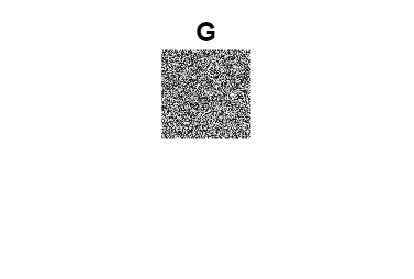

G = rand(81,81);
figure
imshow(G)
title('G'); %rand

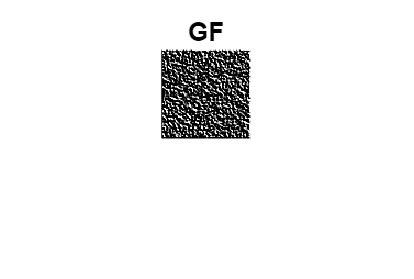


F3 = [0 -1 -1; 1 0 -1; 1 1 0];
GF = filter2(F3, G);
figure
imshow(GF)
title('GF');

The special name of this filter is gradient Filter. From the F3 matrix we can see that it has an enhancement on the 45 degree axis. From the GF plot, we can see that the intensity along the 45 degree axis are more visible. 